# Init

nrVar=1;

## GA


Single objective optimization:
1 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1               60         -0.8688          0.2452        0
    2               88         -0.8688         0.08375        1
    3              116         -0.8688         -0.1777        2
    4              144         -0.8688         -0.3461        3
    5              172         -0.9993         -0.4965        0
    6              200         -0.9993         -0.4723        1
    7              228         -0.9993         -0.6809        2
    8              256         -0.9993         -0.7706        3
    9              284         -0.9993         -0.8971        4
   10              312         -0.9996         -0.9484        0
   11      

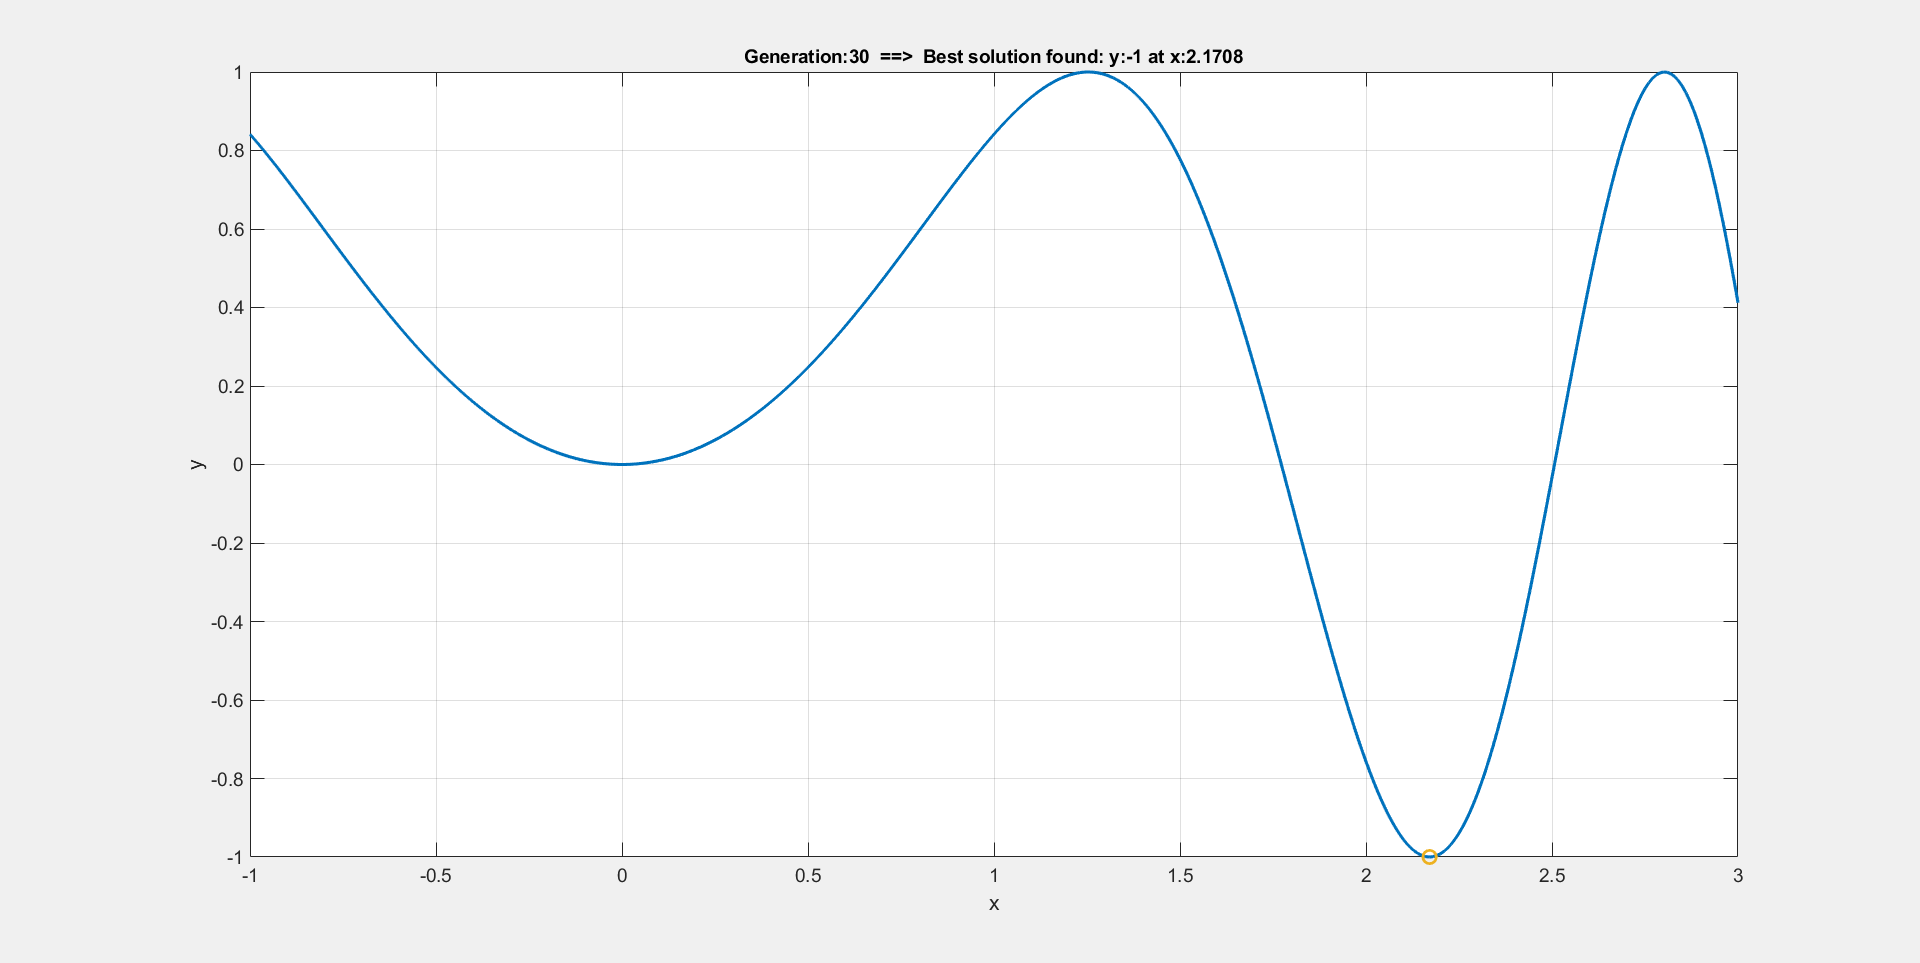

   30              872              -1              -1       10
Optimization terminated: maximum number of generations exceeded.


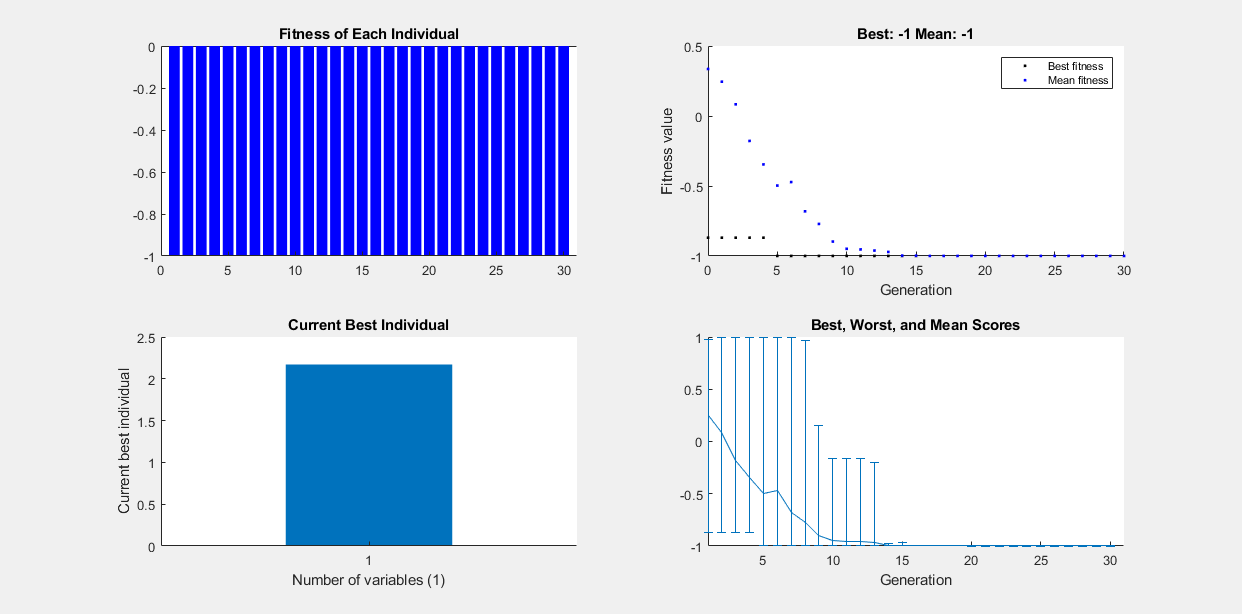

% Set nondefault solver options
options2 = optimoptions("ga","OutputFcn",[@outputFcnTest],"MaxGenerations",30,...
    "PopulationSize",30,"Display","iter","PlotFcn",["gaplotscores",...
    "gaplotbestf","gaplotbestindiv","gaplotrange"]);

% Solve
[solution,objectiveValue] = ga(@objectiveFcn,nrVar,[],[],[],[],repmat(-1,...
    nrVar,1),repmat(3,nrVar,1),[],[],options2);


% Clear variables
clearvars options2

function f = objectiveFcn(optimInput)
% Example:
% Minimize Rosenbrock's function
% f = 100*(y - x^2)^2 + (1 - x)^2

% Edit the lines below with your calculation
x = optimInput(1);
f = sin(x.^2);
end

function [state,options,optchanged] = outputFcnTest(options,state,flag)
optchanged = false;
switch flag

    case 'init'

        fontSize = 14;

        % Plot init
        state.fig=figure;
        state.fig.WindowState = 'maximized';%set(gcf, 'Position', get(0, 'Screensize'));
        set(gcf,'Visible','on'); % to make it visible outside the live editor
        x=-1:0.01:3;
        for ii=1:numel(x)
            y(ii)=objectiveFcn(x(ii));
        end
        state.ax=subplot(1,1,1);
        plot(x,y,'LineWidth',2); grid on; xlabel('x','FontSize', fontSize);ylabel('y','FontSize', fontSize);
        set(gca,'FontSize',fontSize)
        title('Find the global minimun of the function sin(x^2), x=[-1 3]','FontSize', fontSize);

        %test;

    case 'iter'

        % Get top n values
        [~,indTop]      = sort(state.Score);
        topScore        = state.Score(indTop);
        topPopulation   = state.Population(indTop);

        n               = 1;
        topScore        = topScore(1:n);
        topPopulation   = topPopulation(1:n);

        % Plot iter
        %plot(state.ax,topPopulation,topScore,'o');
        hold(state.ax,'on');
        try
            delete(state.p);
        end
        state.p=plot(state.ax,state.Population,state.Score,'o','MarkerSize',10,'LineWidth',2);
        %xlim([-10,10]);ylim([0,100]);
        title(state.ax,['Generation:' num2str(state.Generation) '  ==>  Best solution found: y:' num2str(topScore(1))  ' at x:' num2str(topPopulation(1))]);
        pause(1);
    case 'done'

end
end
